## Задание 4. Еще одно исследование наблюдаемости.

Начальные условия на задание:

A = [-8, -3, -12; 
     -3, -2, -6;
     6, 0, 7];

C = [0 , 1 , 1];

f = @(t)  2*exp(-2*t)*cos(3*t) + exp(-2*t)*sin(3*t);

V = [C;
     C*A;
     C*A^2]

V =      0     1     1
     3    -2     1
   -12    -5   -17


rank(V)

ans = 2

eig(A)

ans =   -2.0000 + 3.0000i
  -2.0000 - 3.0000i
   1.0000 + 0.0000i


l1 = -2 + 3j; l2 = -2 - 3j; l3 = 1;

vpa([A - l1*eye(3); C])

$$ans = \left(\begin{array}{ccc} -6.0-3.0\,\mathrm{i} & -3.0 & -12.0\\ -3.0 & -3.0\,\mathrm{i} & -6.0\\ 6.0 & 0 & 9.0-3.0\,\mathrm{i}\\ 0 & 1.0 & 1.0 \end{array}\right)$$

vpa([A - l2*eye(3); C])

$$ans = \left(\begin{array}{ccc} -6.0+3.0\,\mathrm{i} & -3.0 & -12.0\\ -3.0 & 3.0\,\mathrm{i} & -6.0\\ 6.0 & 0 & 9.0+3.0\,\mathrm{i}\\ 0 & 1.0 & 1.0 \end{array}\right)$$

vpa([A - l3*eye(3); C])

$$ans = \left(\begin{array}{ccc} -9.0 & -3.0 & -12.0\\ -3.0 & -3.0 & -6.0\\ 6.0 & 0 & 6.0\\ 0 & 1.0 & 1.0 \end{array}\right)$$


rank([A - l1*eye(3); ...
           C])

ans = 3

rank([A - l2*eye(3); ...
           C])

ans = 3

rank([A - l3*eye(3); ...
           C])

ans = 2

Матрица Хаутуса для наблюдаемости имеет полный ранг при всех собственных числах матрицы А --> **ДА**

Проверка критерия по Жордану (функция в матлабе немного криво реализована):

[P, Aj] = jordan(A);
[P2, Aj2] = cdf2rdf(P, Aj)

P2 =    -1.0000   -2.1213   -0.7071
   -1.0000   -0.7071   -0.7071
    1.0000    1.4142         0


Aj2 =      1     0     0
     0    -2    -3
     0     3    -2



vpa(Aj2) % теперь их соотносим

$$ans = \left(\begin{array}{ccc} 1.0 & 0 & 0\\ 0 & -2.0 & -3.0\\ 0 & 3.0 & -2.0 \end{array}\right)$$

vpa(C*P) % теперь их соотносим

$$ans = \left(\begin{array}{ccc} 0 & 0.5-0.5\,\mathrm{i} & 0.5+0.5\,\mathrm{i} \end{array}\right)$$

Полностью наблюдаема, так как первый столбец C не равен нулю, и каждая клетка соответствует разным соб. числам.

Ищем Грамиан Наблюдаемости

% B = zeros([3, 1]) ; D = zeros([1, 1]);
% sys = ss(A,B,C,D)
% observe_gram = gram(sys, 'o')
% eig_values_gram = eig(observe_gram)

t1 = 3;
Q = @(t) expm((A.') * t) * (C.') * C * expm(A*t);
observe_gram = integral(Q, 0, t1, 'ArrayValued',true)

observe_gram =     0.0865    0.0577    0.1442
    0.0577    0.1635    0.2212
    0.1442    0.2212    0.3654


eig_values_gram = eig(observe_gram)

eig_values_gram =     0.5571
    0.0582
   -0.0000


Так как все положительные, то значит матрица Наблюдаемости положительно определена

Определить начальные условия системы + моделирование

**y(t) == f(t) в начале задания !!!**

time = linspace(0, t1, 3000);
y_values = zeros(1, length(time));
y_exp_values = zeros(1, length(time));
x_values = zeros(3, length(time)); 

for i = 1:length(time)
    y_values(i) = f(time(i));
end

INT = @(t) expm(A.' * t) * (C.') * f(t);
x0 = pinv(observe_gram) * integral(INT, 0, t1, 'ArrayValued',true)

x0 =    -0.0000
    1.0000
    1.0000


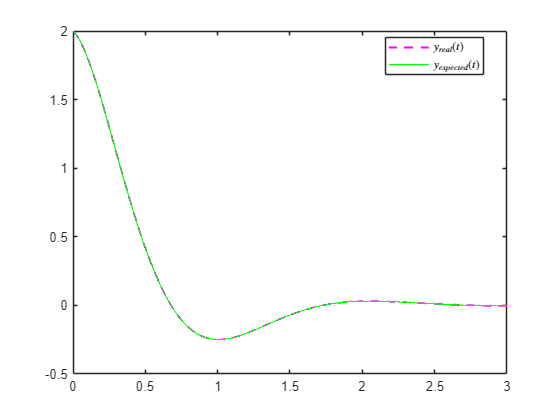


expmA = @(t) expm(A * (t1 - t) ) * B * u(t);

for i = 1:length(time)
    x_values(:, i) = expm(A*time(i))*x0;
    y_exp_values(i) = C*expm(A*time(i))*x0;
end

h = figure;
xlabel('time [s]');                                   
grid on;
plot(time, y_values, 'magenta--', 'LineWidth', 1.5); hold on;
plot(time, y_exp_values, 'g', 'LineWidth', 1.0); 
legend('$y_{real}(t)$', '$y_{expected}(t)$', ...
        'Location', 'best', 'Interpreter', 'latex');
save_file("output2");

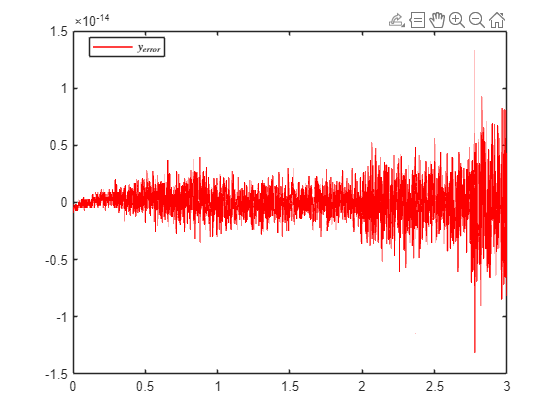


h = figure;
xlabel('time [s]');                                   
grid on;
plot(time, y_values - y_exp_values, 'r', 'LineWidth', 1.0); hold on;
legend('$y_{error}$', 'Location', 'best', 'Interpreter', 'latex');
save_file("error2");

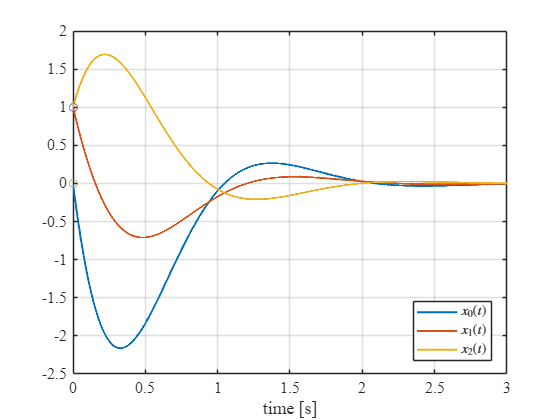


h = figure;
set(h,'DefaultAxesFontSize', 12, 'DefaultAxesFontName','Times New Roman');
plot(time, x_values(1, :), 'LineWidth', 1.5); hold on;
plot(time, x_values(2, :), 'LineWidth', 1.5);
plot(time, x_values(3, :), 'LineWidth', 1.5);
plot(0, 1, 'o');plot(0, 0, 'o');
title(' ');   
xlabel('time [s]');                                   
grid on;
legend('$x_0(t)$', '$x_1(t)$', '$x_2(t)$', ...
       'Location', 'best', 'Interpreter', 'latex');
save_file("observability2");

Поиск плохих, `Альтернативные начальные условия`

% why it didn't worked ???
% for i = 1:length(time)
%     x_values(:, i) = expm(A*time(i))*x0;
%     x2_values(:, i) = expm(A*time(i))*x02;
%     y_exp_values(i) = C*expm(A*time(i))*x0;
%     y_exp2_values(i) = C*expm(A*time(i))*x02;
% end

null(V)

ans =    -0.5774
   -0.5774
    0.5774


x2_values = zeros(3, length(time)); 
y_exp2_values = zeros(3, length(time));

for i = 1:length(time)
    y_values(i) = f(time(i));
end

t_lim = 3;
INT = @(t) expm(A.' * t) * (C.') * f(t);
x0 = pinv(observe_gram) * integral(INT, 0, t_lim, 'ArrayValued',true)

x0 =    -0.0000
    1.0000
    1.0000



x01 = x0 + 1 .* null(V)

x01 =    -0.5774
    0.4226
    1.5774


x02 = x0 + 5 .* null(V)

x02 =    -2.8868
   -1.8868
    3.8868


x03 = x0 + 100 .* null(V)

x03 =   -57.7350
  -56.7350
   58.7350


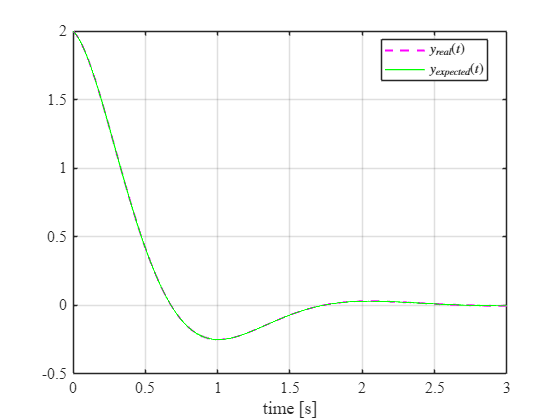


sys = ss(A, [0; 0; 0], C, []);
u = zeros(1, length(time));
[y_hat1, t1, x1] = lsim(sys, u, time, x01);
[y_hat2, t2, x2] = lsim(sys, u, time, x02);
[y_hat3, t3, x3] = lsim(sys, u, time, x03);
%%%%%%%%%%%%%%%%%%%
h = figure;
set(h,'DefaultAxesFontSize', 12, 'DefaultAxesFontName','Times New Roman');
plot(time, y_values, 'magenta--', 'LineWidth', 1.5); hold on;
plot(time, y_hat1, 'g', 'LineWidth', 1.0); 
grid on;
xlabel('time [s]');                                   
legend('$y_{real}(t)$', '$y_{expected}(t)$', ...
        'Location', 'best', 'Interpreter', 'latex');
save_file("output3");

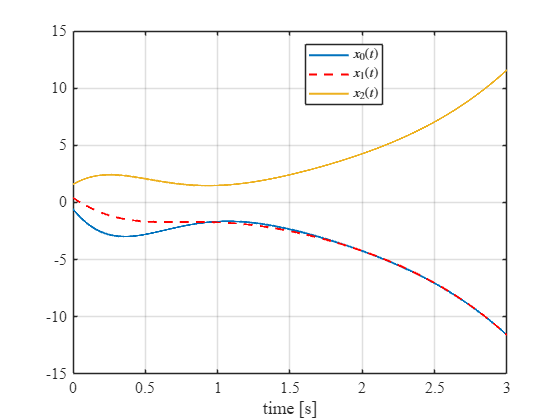


h = figure;
set(h,'DefaultAxesFontSize', 12, 'DefaultAxesFontName','Times New Roman');
plot(time, x1(:, 1), 'LineWidth', 1.5); hold on;
plot(time, x1(:, 2),'r--', 'LineWidth', 1.5);
plot(time, x1(:, 3), 'LineWidth', 1.5);
title(' ');   
xlabel('time [s]');                                   
grid on;
legend('$x_0(t)$', '$x_1(t)$', '$x_2(t)$', ...
       'Location', 'best', 'Interpreter', 'latex');
save_file("observability3");

%%%%%%%%%%%%%%%%%%%
%%%%%%%%%%%%%%%%%%%
h = figure;
set(h,'DefaultAxesFontSize', 12, 'DefaultAxesFontName','Times New Roman');
plot(time, y_values, 'magenta--', 'LineWidth', 1.5); hold on;
plot(time, y_hat2, 'g', 'LineWidth', 1.0); 
grid on;
xlabel('time [s]');                                   
legend('$y_{real}(t)$', '$y_{expected}(t)$', ...
        'Location', 'best', 'Interpreter', 'latex');
save_file("output4");

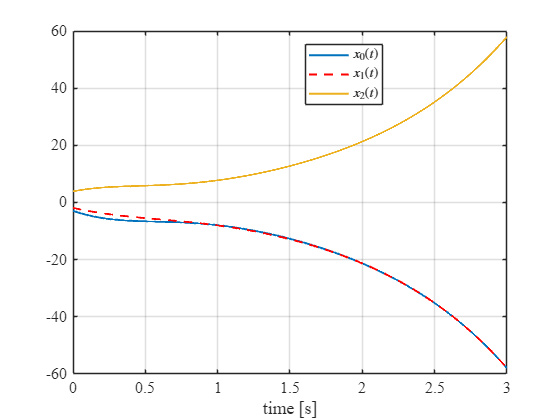


h = figure;
set(h,'DefaultAxesFontSize', 12, 'DefaultAxesFontName','Times New Roman');
plot(time, x2(:, 1), 'LineWidth', 1.5); hold on;
plot(time, x2(:, 2), 'r--', 'LineWidth', 1.5);
plot(time, x2(:, 3), 'LineWidth', 1.5);
title(' ');   
xlabel('time [s]');                                   
grid on;
legend('$x_0(t)$', '$x_1(t)$', '$x_2(t)$', ...
       'Location', 'best', 'Interpreter', 'latex');
save_file("observability4");

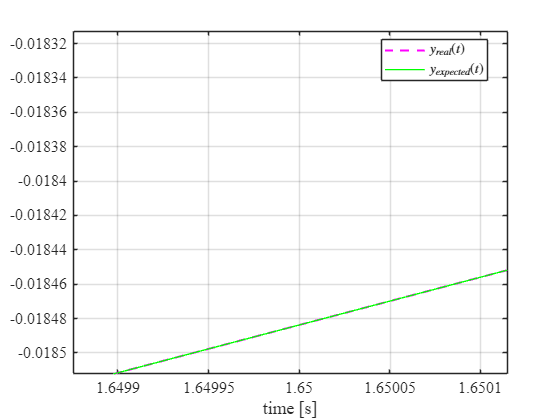

%%%%%%%%%%%%%%%%%%%
%%%%%%%%%%%%%%%%%%%
h = figure;
set(h,'DefaultAxesFontSize', 12, 'DefaultAxesFontName','Times New Roman');
plot(time, y_values, 'magenta--', 'LineWidth', 1.5); hold on;
plot(time, y_hat3, 'g', 'LineWidth', 1.0); 
grid on;
xlabel('time [s]');                                   
legend('$y_{real}(t)$', '$y_{expected}(t)$', ...
        'Location', 'best', 'Interpreter', 'latex');
save_file("output5");

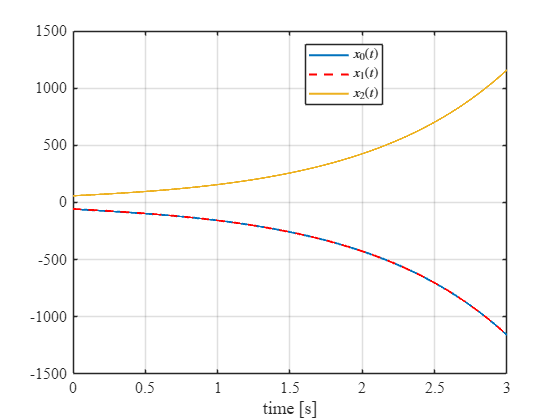


h = figure;
set(h,'DefaultAxesFontSize', 12, 'DefaultAxesFontName','Times New Roman');
plot(time, x3(:, 1), 'LineWidth', 1.5); hold on;
plot(time, x3(:, 2), 'r--','LineWidth', 1.5);
plot(time, x3(:, 3), 'LineWidth', 1.5);
title(' ');   
xlabel('time [s]');                                   
grid on;
legend('$x_0(t)$', '$x_1(t)$', '$x_2(t)$', ...
       'Location', 'best', 'Interpreter', 'latex');
save_file("observability5");

%%%%%%%%%%%%%%%%%%%

**Функция, чтобы сохранить картинку в папку**

function save_file(name)
    path = 'D:\Math\control_theory\control_theory_labs\lab7\latex7\images';
    fullpath = fullfile(path, name);
    saveas(gcf, fullpath, 'png');

end